**Global setting**

clc
clear
close all
rng(122)

## Data prepare

x =(0:0.5:3)'; 
% x = [x ;10];
f = 1*exp(-0.2.*x);
y = f + 0.03.*randn(length(x),1);
z = (0:0.1:15)';


## GP model setting

% default zero mean function
cov = @covSEiso; lik = @likGauss; inf = @infExact;
sn =0.1; hyp.cov = [1,1];hyp.lik = log(sn);
hypTrain1 = minimize(hyp, @gp, -500, inf, [], cov, lik, x, y);

Function evaluation      0;  Value -9.413375e-02
Function evaluation      7;  Value -7.963622e+00
Function evaluation     10;  Value -8.204101e+00
Function evaluation     13;  Value -8.247477e+00
Function evaluation     17;  Value -8.254086e+00
Function evaluation     19;  Value -8.254153e+00
Function evaluation     21;  Value -8.254237e+00
Function evaluation     23;  Value -8.254253e+00
Function evaluation     26;  Value -8.254254e+00
Function evaluation     28;  Value -8.254254e+00
Function evaluation     30;  Value -8.254254e+00
Function evaluation     32;  Value -8.254254e+00
Function evaluation     35;  Value -8.254254e+00
Function evaluation     37;  Value -8.254254e+00
Function evaluation     39;  Value -8.254254e+00
Function evaluation     41;  Value -8.254254e+00
Function evaluation     47;  Value -8.254254e+00


% nlml_new = gp(hyp1, inf, [], cov, lik, x, y);

[mSM,s2] = gp(hypTrain1, inf, [], cov, lik, x, y, z);

%% exp mean function
sn =0.1; hyp2.cov = [1,1];hyp2.lik = log(sn); hyp2.mean = [1,-0.2]';
mean = @meanExp;
hypTrain2 = minimize(hyp2, @gp, -500, inf, mean, cov, lik, x, y);

Function evaluation      0;  Value -1.609434e-01
Function evaluation      7;  Value -1.228117e+01


% nlml_new = gp(hyp1, inf, [], cov, lik, x, y);
[mExp,s2Exp] = gp(hypTrain2, inf, mean, cov, lik, x, y, z);

## Make plot

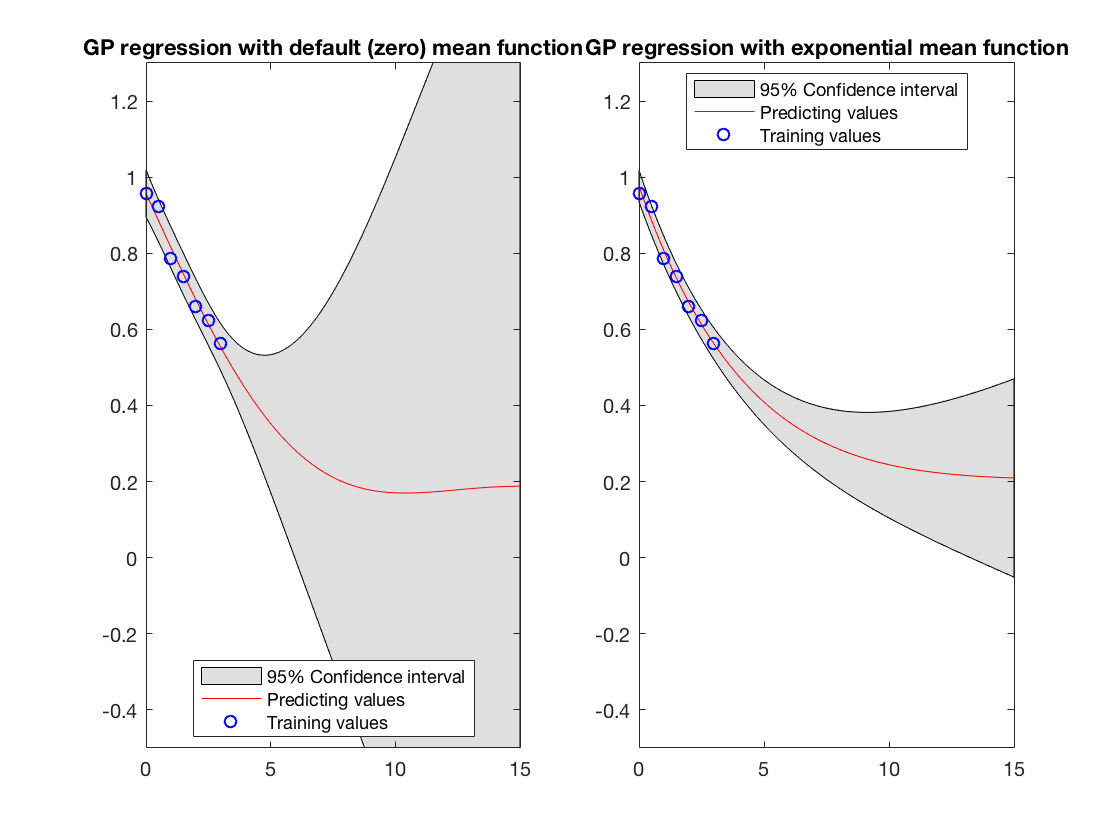

f1 = [mSM+1.96*sqrt(s2); flip(mSM-1.96*sqrt(s2),1)];
f2 = [mExp+1.96*sqrt(s2Exp); flip(mExp-1.96*sqrt(s2Exp),1)];

subplot(1,2,1)
fill([z; flip(z,1)], f1, [7 7 7]/8)
hold on;
plot(z, mSM,'r');
hold on;
plot(x, y, 'bo')
title('GP regression with default (zero) mean function')
legend('95% Confidence interval','Predicting values','Training values','Location','Best');
 ylim([-0.5 1.3])  

subplot(1,2,2)
% figure
fill([z; flip(z,1)], f2, [7 7 7]/8)
hold on;
plot(z, mExp,'r');
hold on;
plot(x, y, 'bo')
title('GP regression with exponential mean function')
legend('95% Confidence interval','Predicting values','Training values','Location','Best');
 ylim([-0.5 1.3]) 

## One point added

clc
clear
close all
rng(122)
x =(0:0.5:3)'; 
x = [x; 10];
f = 1*exp(-0.2.*x);
y = f + 0.03.*randn(length(x),1);
z = (0:0.1:15)';
ytrue = 1*exp(-0.2.*z);

%% default zero mean function
cov = @covSEiso; lik = @likGauss; inf = @infExact;
sn =0.1; hyp.cov = [1,1];hyp.lik = log(sn);


hypTrain1 = minimize(hyp, @gp, -500, inf, [], cov, lik, x, y);

Function evaluation      0;  Value 1.820316e+00
Function evaluation      8;  Value -7.563895e+00
Function evaluation     11;  Value -8.143951e+00
Function evaluation     14;  Value -8.183657e+00
Function evaluation     16;  Value -8.241936e+00
Function evaluation     19;  Value -8.244032e+00
Function evaluation     21;  Value -8.244058e+00
Function evaluation     23;  Value -8.244061e+00
Function evaluation     25;  Value -8.244063e+00
Function evaluation     26;  Value -8.244064e+00
Function evaluation     29;  Value -8.244064e+00
Function evaluation     31;  Value -8.244064e+00
Function evaluation     33;  Value -8.244064e+00
Function evaluation     35;  Value -8.244064e+00
Function evaluation     37;  Value -8.244064e+00
Function evaluation     39;  Value -8.244064e+00
Function evaluation     41;  Value -8.244064e+00
Function evaluation     43;  Value -8.244064e+00
Function evaluation     45;  Value -8.244064e+00
Function evaluation     50;  Value -8.244064e+00


% nlml_new = gp(hyp1, inf, [], cov, lik, x, y);

[mSM,s2] = gp(hypTrain1, inf, [], cov, lik, x, y, z);

%% exp mean function
sn =0.1; hyp2.cov = [1,1];hyp2.lik = log(sn); hyp2.mean = [1,-0.2]';
mean = @meanExp;
hypTrain2 = minimize(hyp2, @gp, -500, inf, mean, cov, lik, x, y);

Function evaluation      0;  Value 1.752901e+00
Function evaluation      7;  Value -1.365953e+01


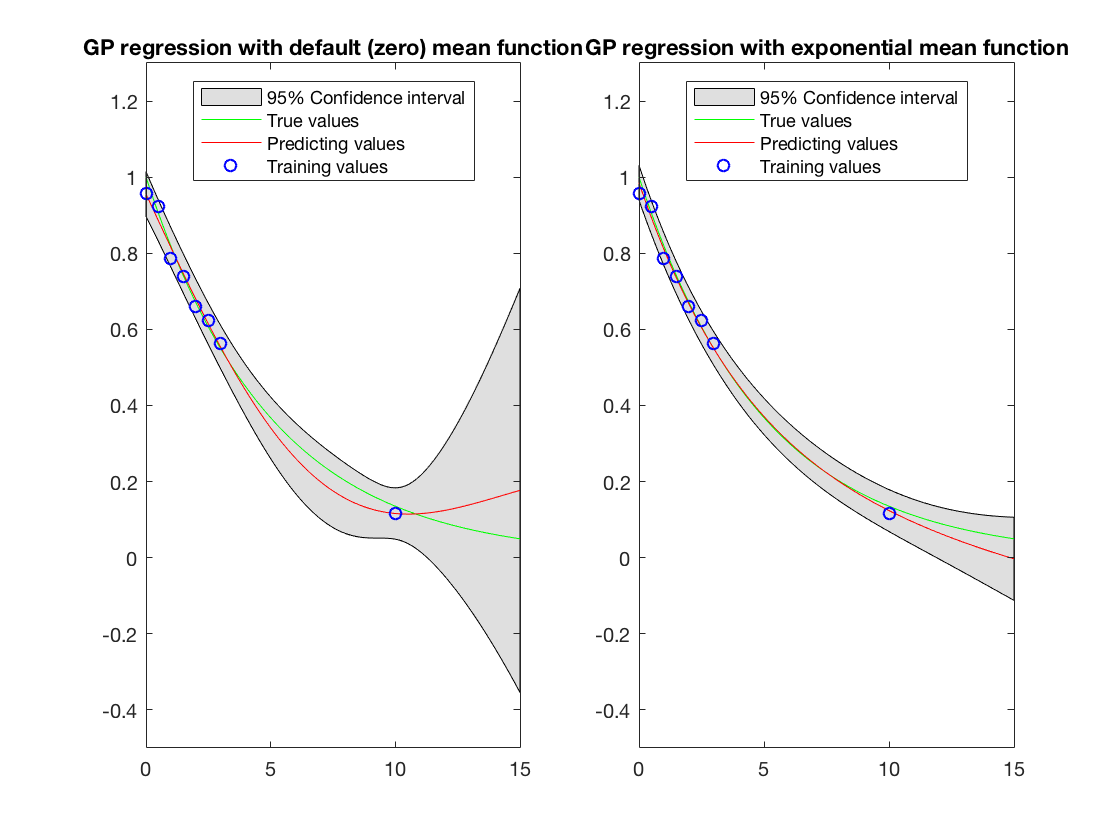

% nlml_new = gp(hyp1, inf, [], cov, lik, x, y);

[mExp,s2Exp] = gp(hypTrain2, inf, mean, cov, lik, x, y, z);

%%

f1 = [mSM+1.96*sqrt(s2); flip(mSM-1.96*sqrt(s2),1)];
f2 = [mExp+1.96*sqrt(s2Exp); flip(mExp-1.96*sqrt(s2Exp),1)];

subplot(1,2,1)
fill([z; flip(z,1)], f1, [7 7 7]/8)
hold on;
plot(z, ytrue,'g');
hold on;
plot(z, mSM,'r');
hold on;
plot(x, y, 'bo')
title('GP regression with default (zero) mean function')
legend('95% Confidence interval','True values','Predicting values',...
    'Training values','Location','Best');
 ylim([-0.5 1.3])  

subplot(1,2,2)
% figure
fill([z; flip(z,1)], f2, [7 7 7]/8)
hold on;
plot(z, ytrue,'g');
hold on;
plot(z, mExp,'r');
hold on;
plot(x, y, 'bo')
title('GP regression with exponential mean function')
legend('95% Confidence interval','True values','Predicting values',...
    'Training values','Location','Best');
 ylim([-0.5 1.3])  